## Mesh processing toolbox

### Author & support : nicolas.douillet (at) free.fr, 2020.

### Example #1 : vertex normals

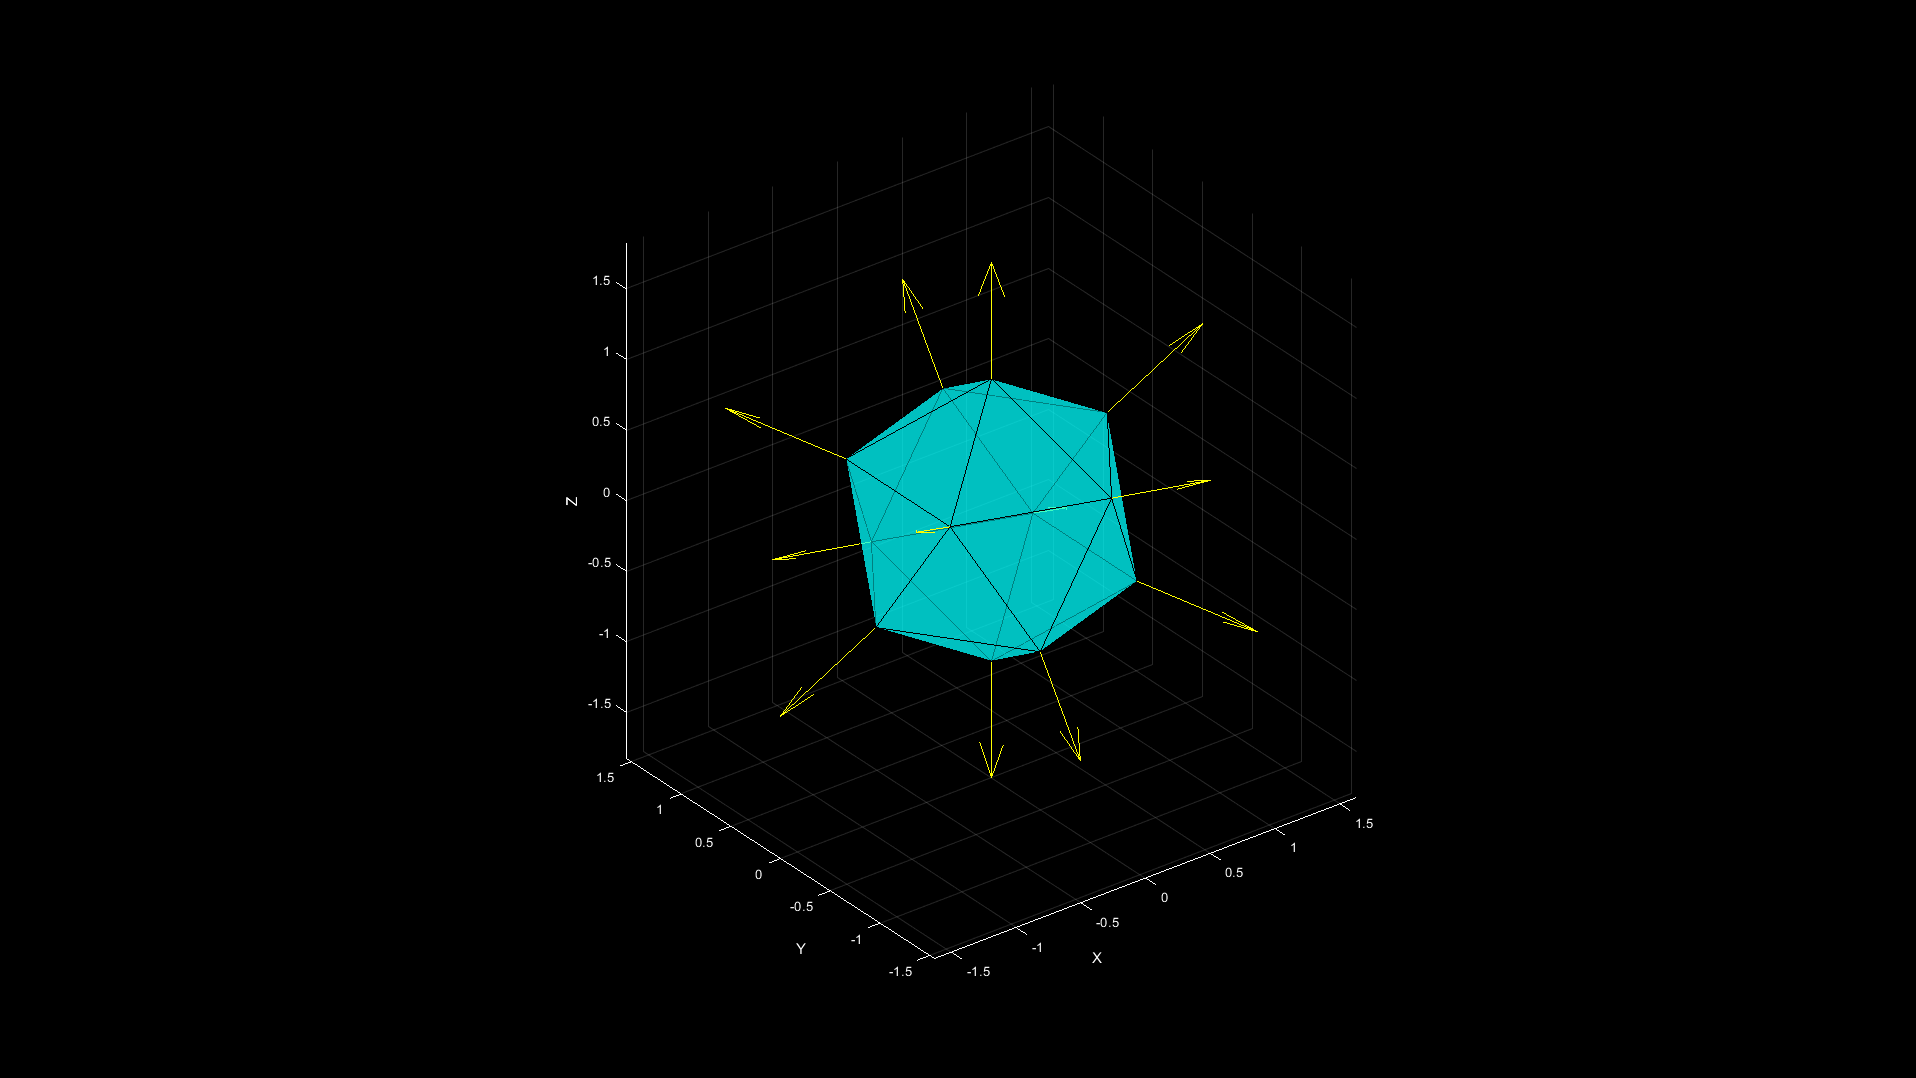

Mesh with 12 vertices and 20 triangles displayed in 8.624460e-02 seconds.


addpath('data/');
addpath('src/');

load('icosahedron.mat');
ngb_degre = 1;
select_vertex_normals(V,T,ngb_degre);

### Example #2 : non manifold triangles

load('kitten_nmnfld.mat');
nmnfld_tgl_idx_list = select_non_manifold_triangles(V,T);

Mesh with 5224 vertices and 10911 triangles displayed in 6.956640e-02 seconds.


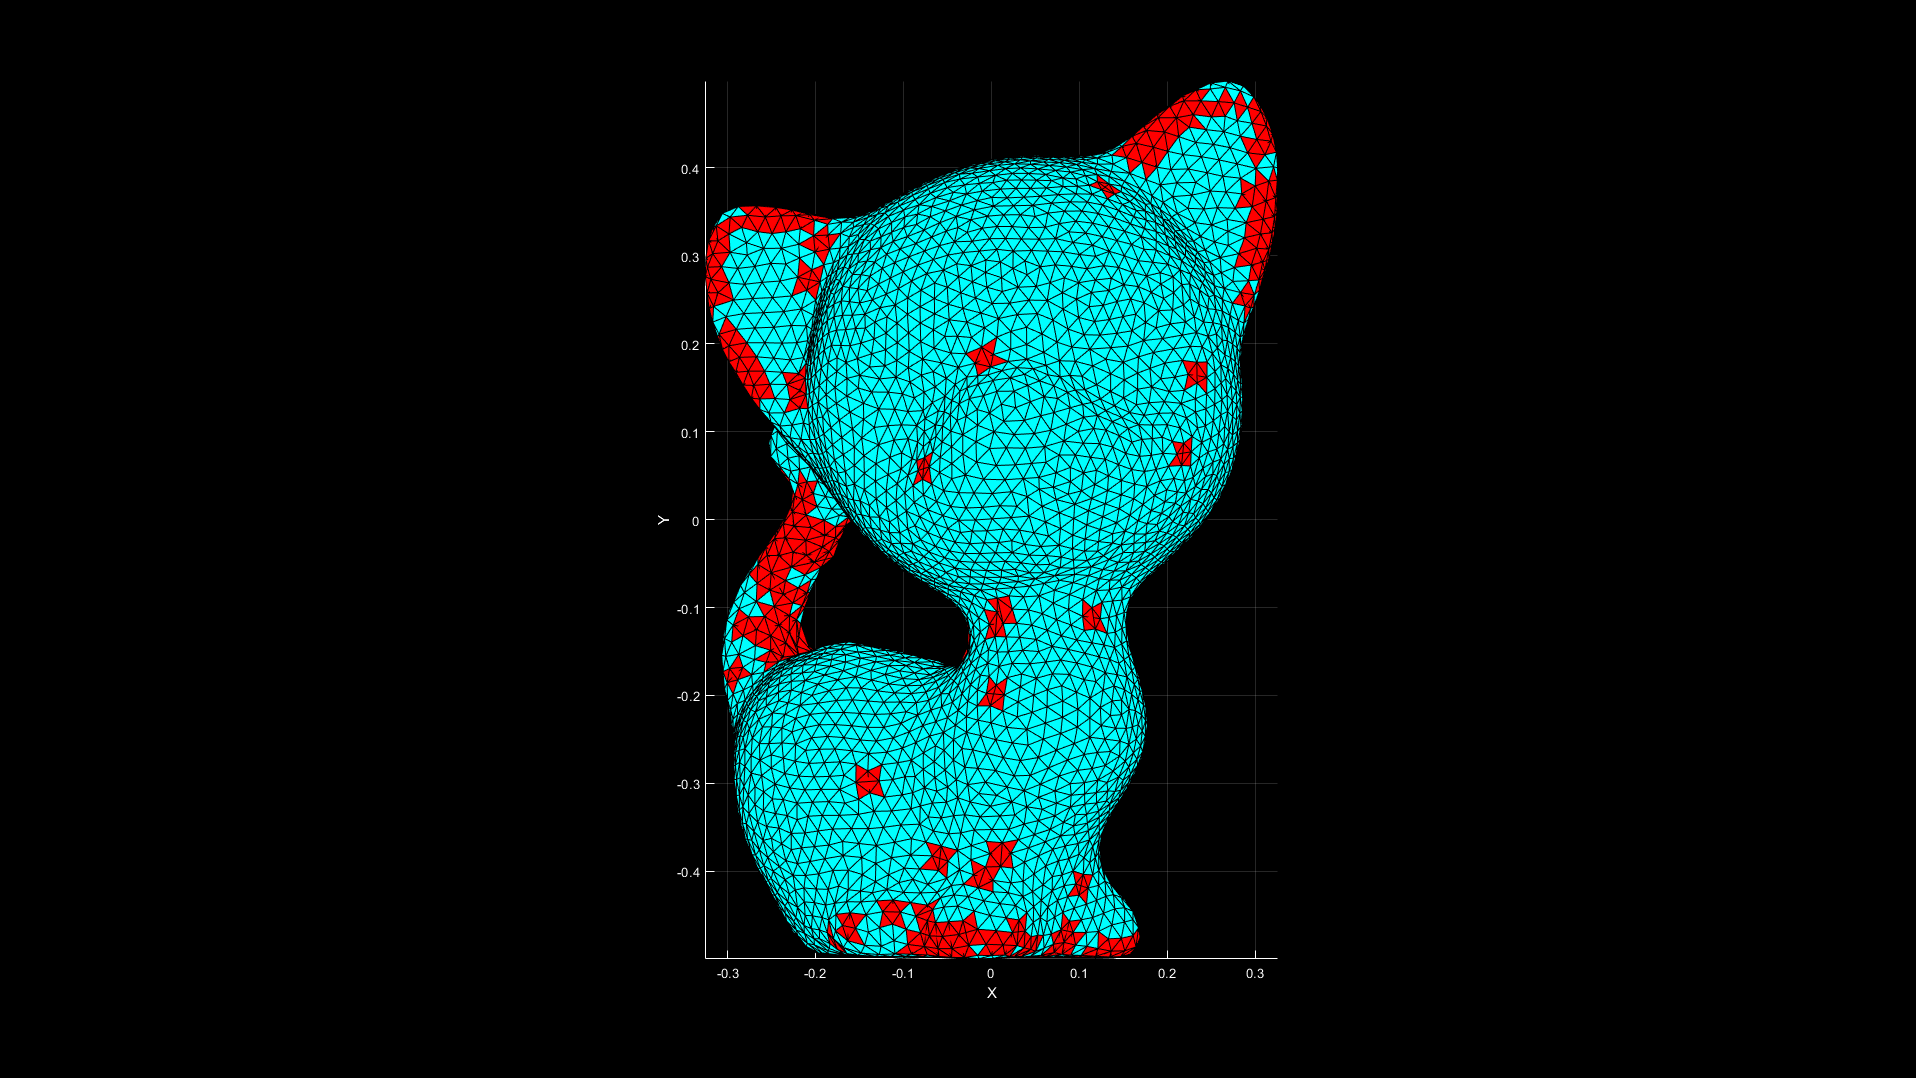

view(0,90);

### Example #3 : connected components

load('kitten_components.mat');
[cc_nb,components] = segment_connected_components(T);

4 components found in 1.373156e+00 seconds.


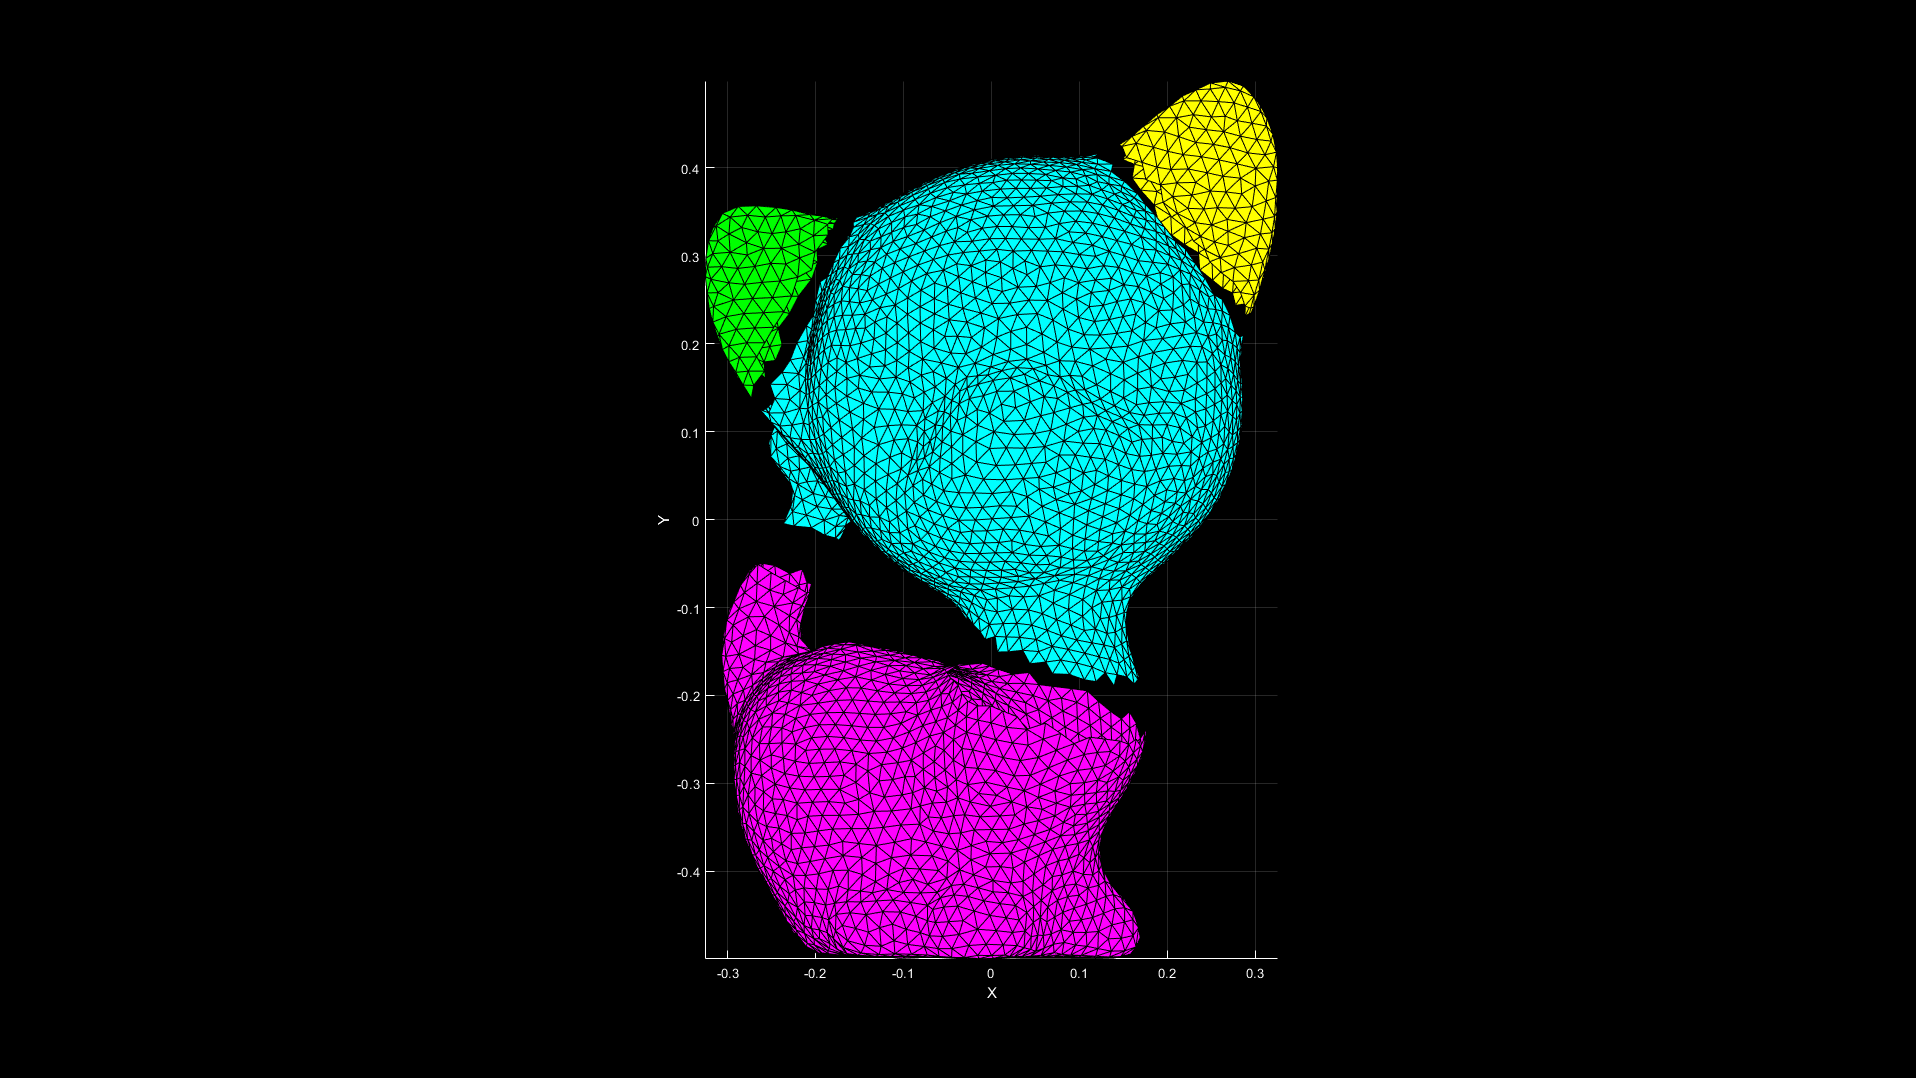

show_mesh_components(V,components);
view(0,90);

### Example #4 : holes and boundary selection

load('kitten_holed.mat');
nmnfld_vtx_idx = select_non_manifold_vertices(V,T,false);
[V,T] = clone_solve_nmnfld_vertices(V,T,nmnfld_vtx_idx);

1 components found in 4.305500e-03 seconds.
1 components found in 3.886000e-04 seconds.
1 components found in 2.183000e-04 seconds.
1 components found in 7.117300e-03 seconds.
2 components found in 2.031000e-03 seconds.
duplicate_nmnfld_vertices request executed in 5.086700e-02 seconds. 5 clone vertices added.


boundaries = select_holes_and_boundary(V,T);

6 boundaries detected in 5.954640e-02 seconds.


Mesh with 5120 vertices and 10115 triangles displayed in 7.355420e-02 seconds.


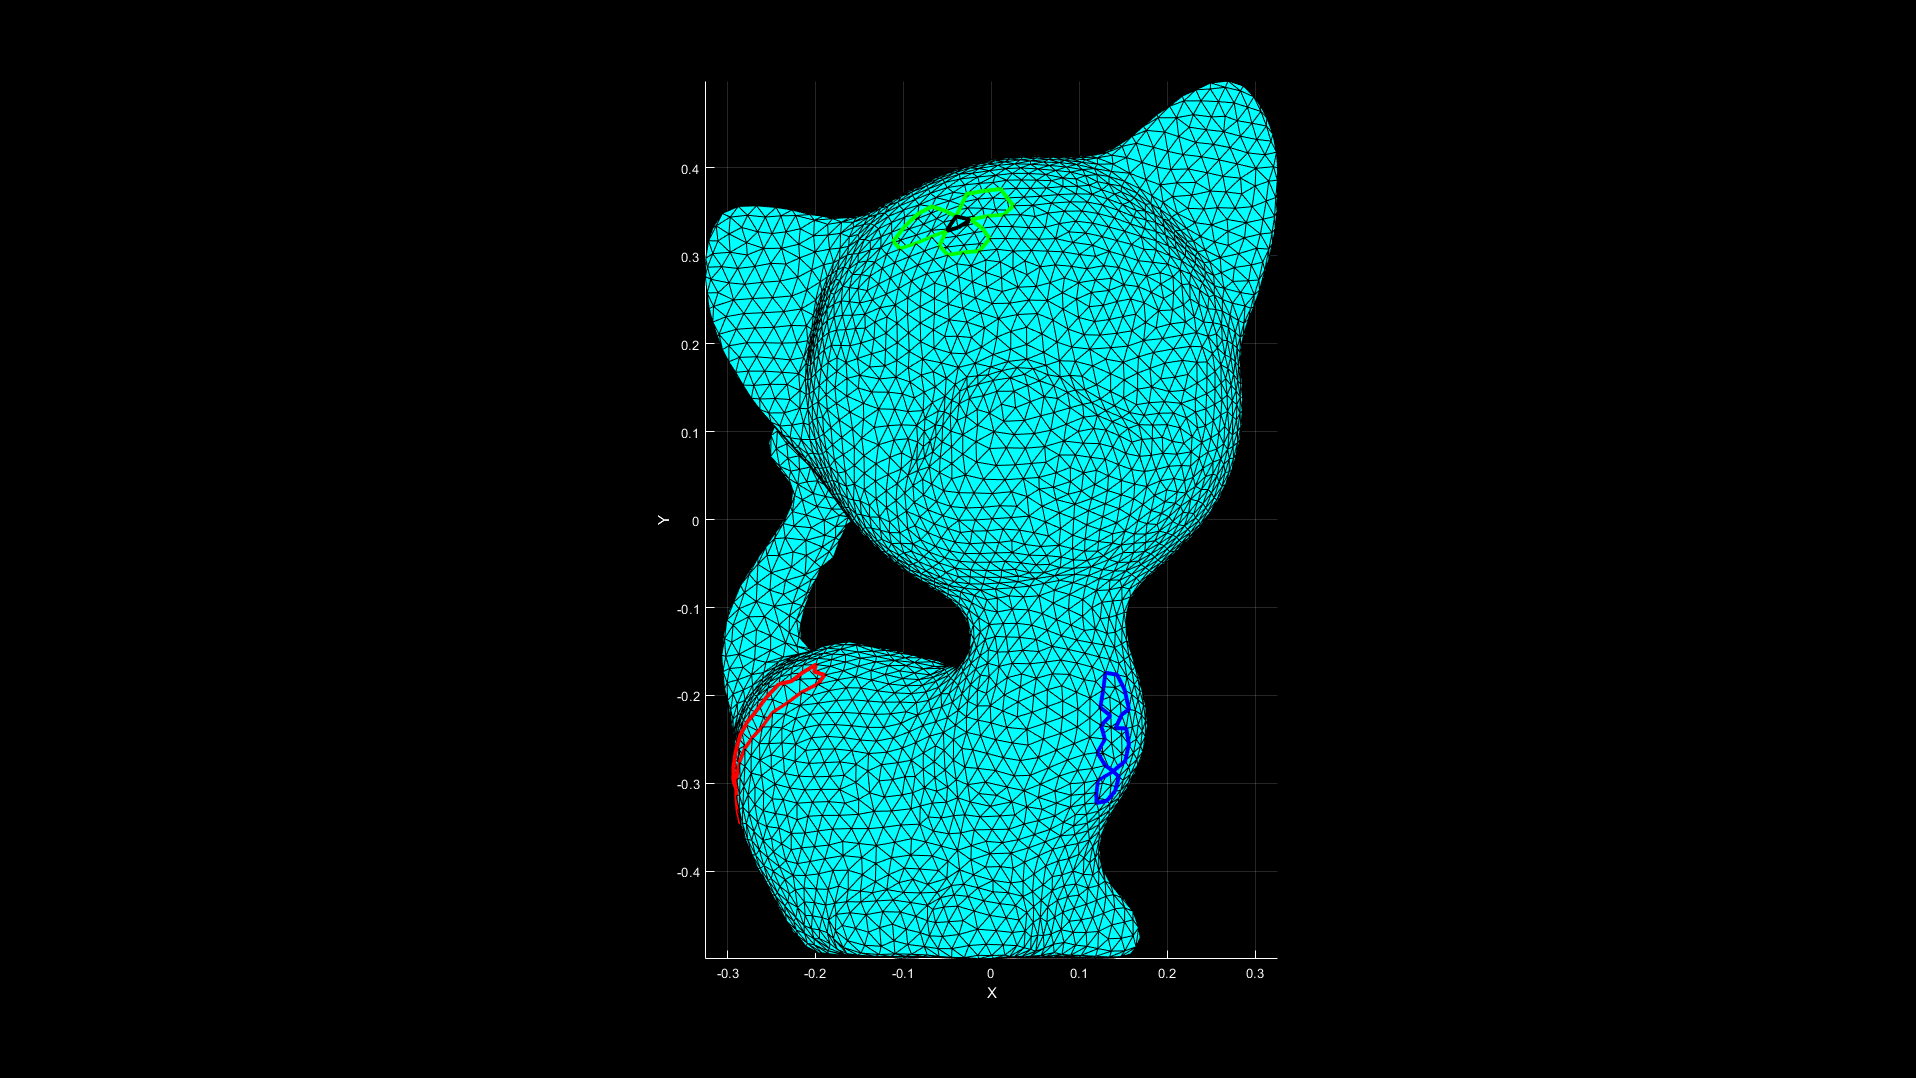

view(0,90);

### Example #5 : hole filling

[V,T] = remove_non_manifold_vertices(V,T);

0 non manifold vertices removed in 7.494052e-01 seconds.


boundaries = select_holes_and_boundary(V,T);

6 boundaries detected in 5.164960e-02 seconds.


Mesh with 5120 vertices and 10115 triangles displayed in 6.617640e-02 seconds.


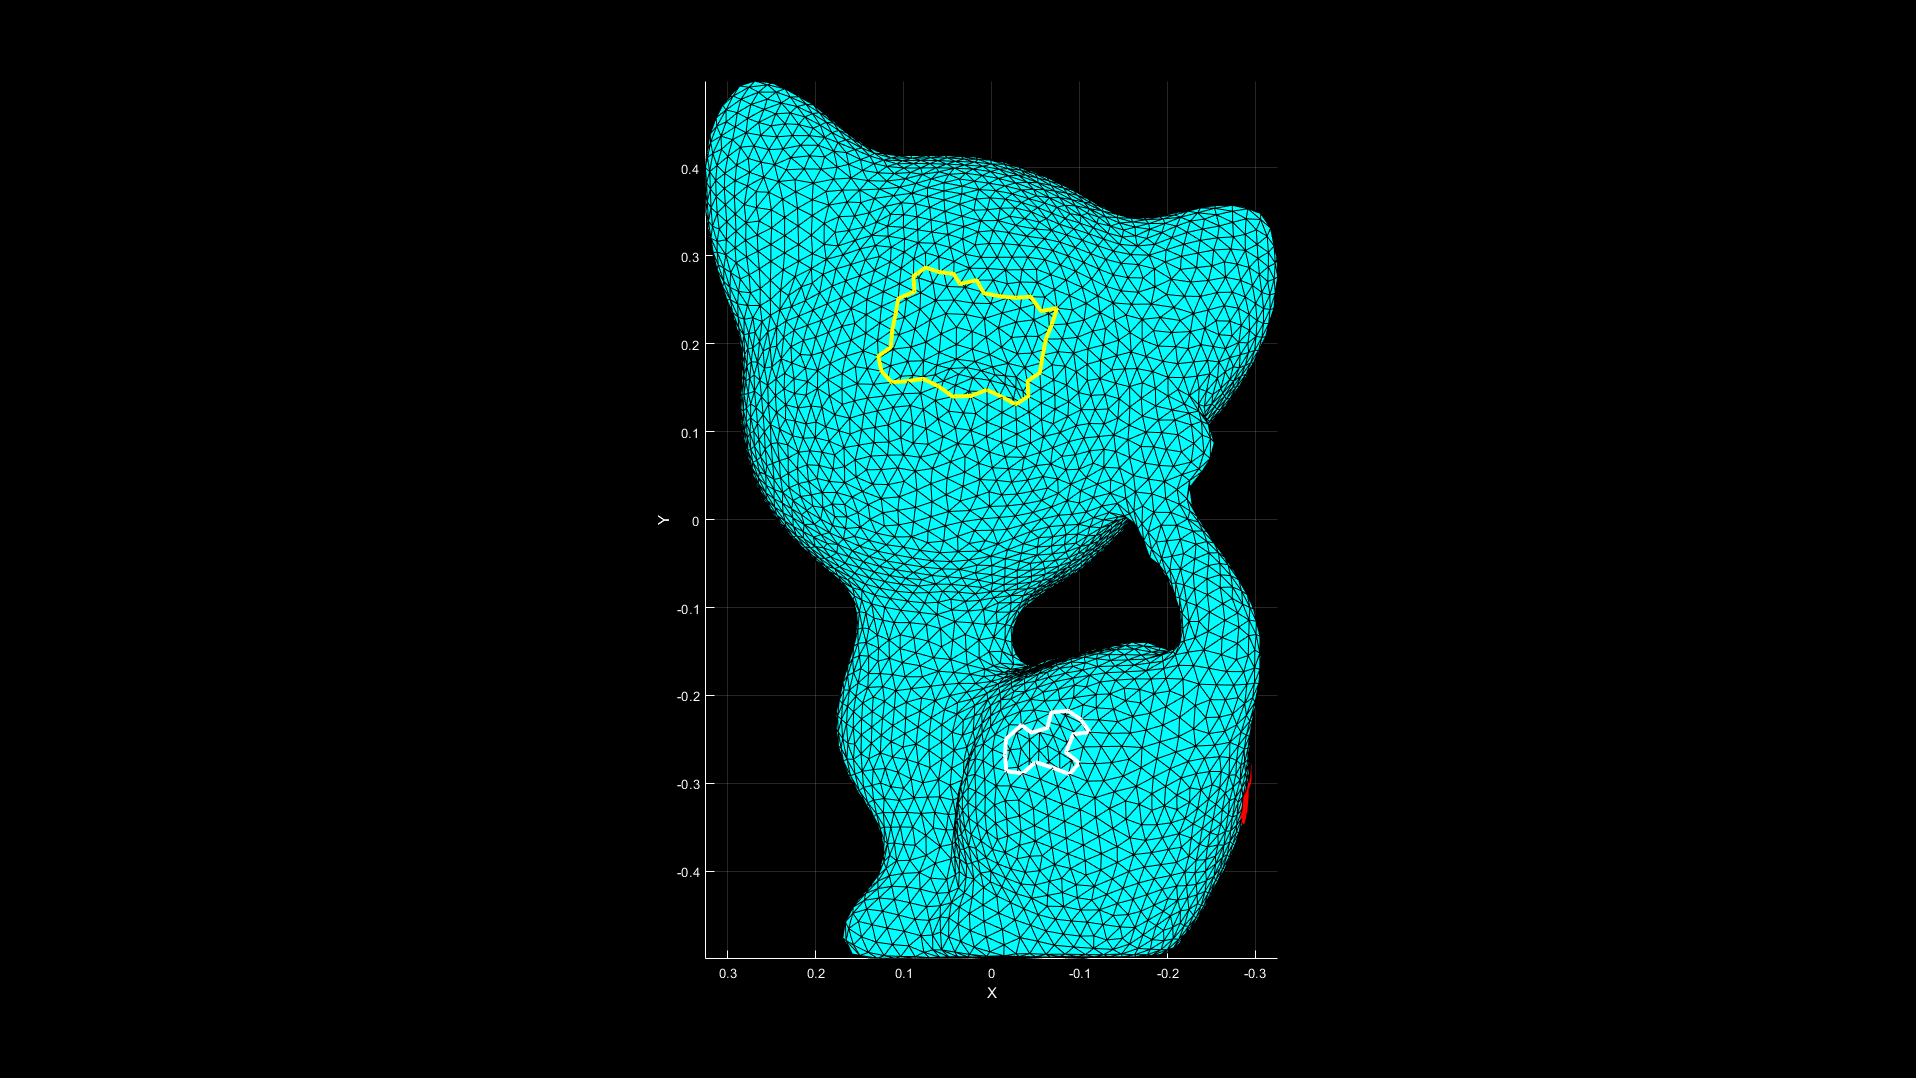

view(-180,-90);


max_perim_sz = 200;
T = fill_mesh_holes(V,T,boundaries,'closed',max_perim_sz);

6 hole(s) filled by adding 121 triangles in 4.226778e-01 seconds.


plot_mesh(V,T);

Mesh with 5120 vertices and 10236 triangles displayed in 6.751370e-02 seconds.


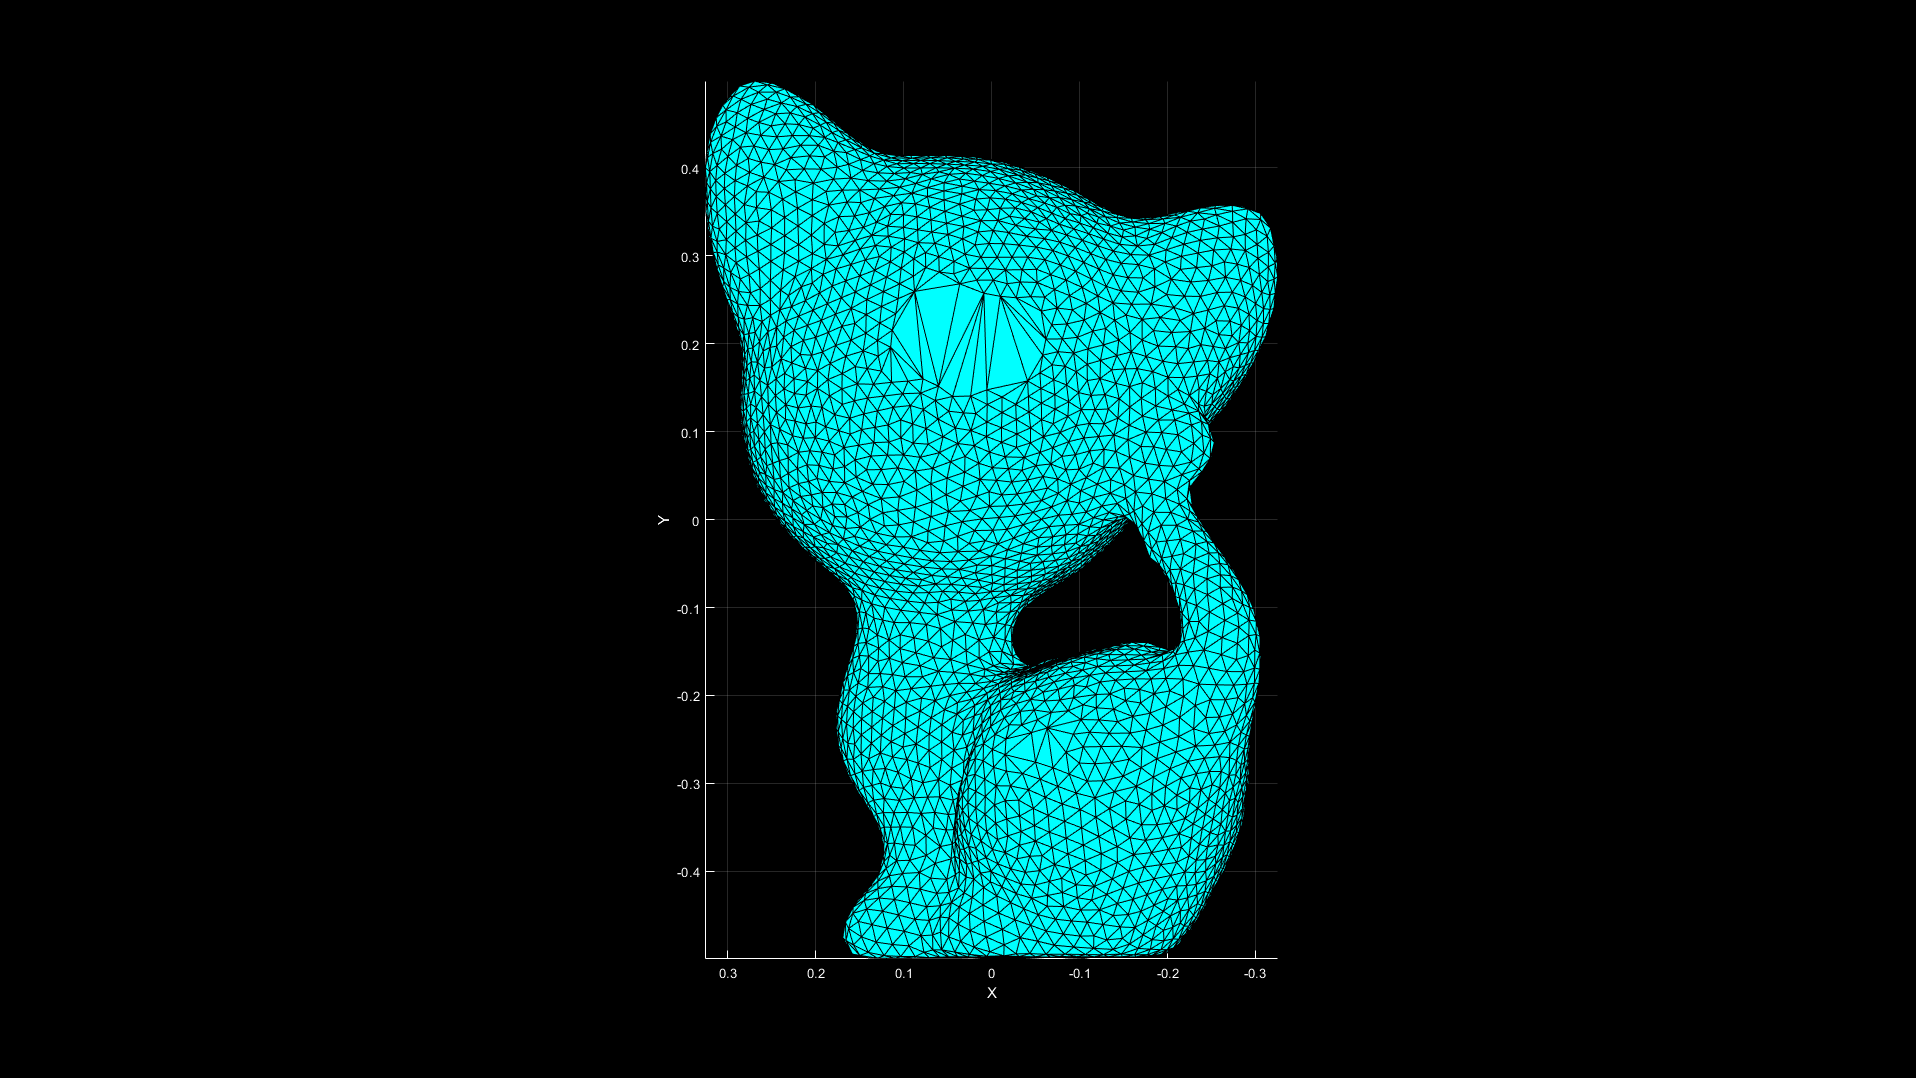

view(-180,-90);

### Example #6 : curvature

load('kitten.mat');
ngb_degre = 2;
N = compute_vertex_normals(V,T,ngb_degre,'raw');
curvature = compute_mesh_curvature(V,T,N,ngb_degre,'mean');

mean curvature computed in 6.015872e-01 seconds.


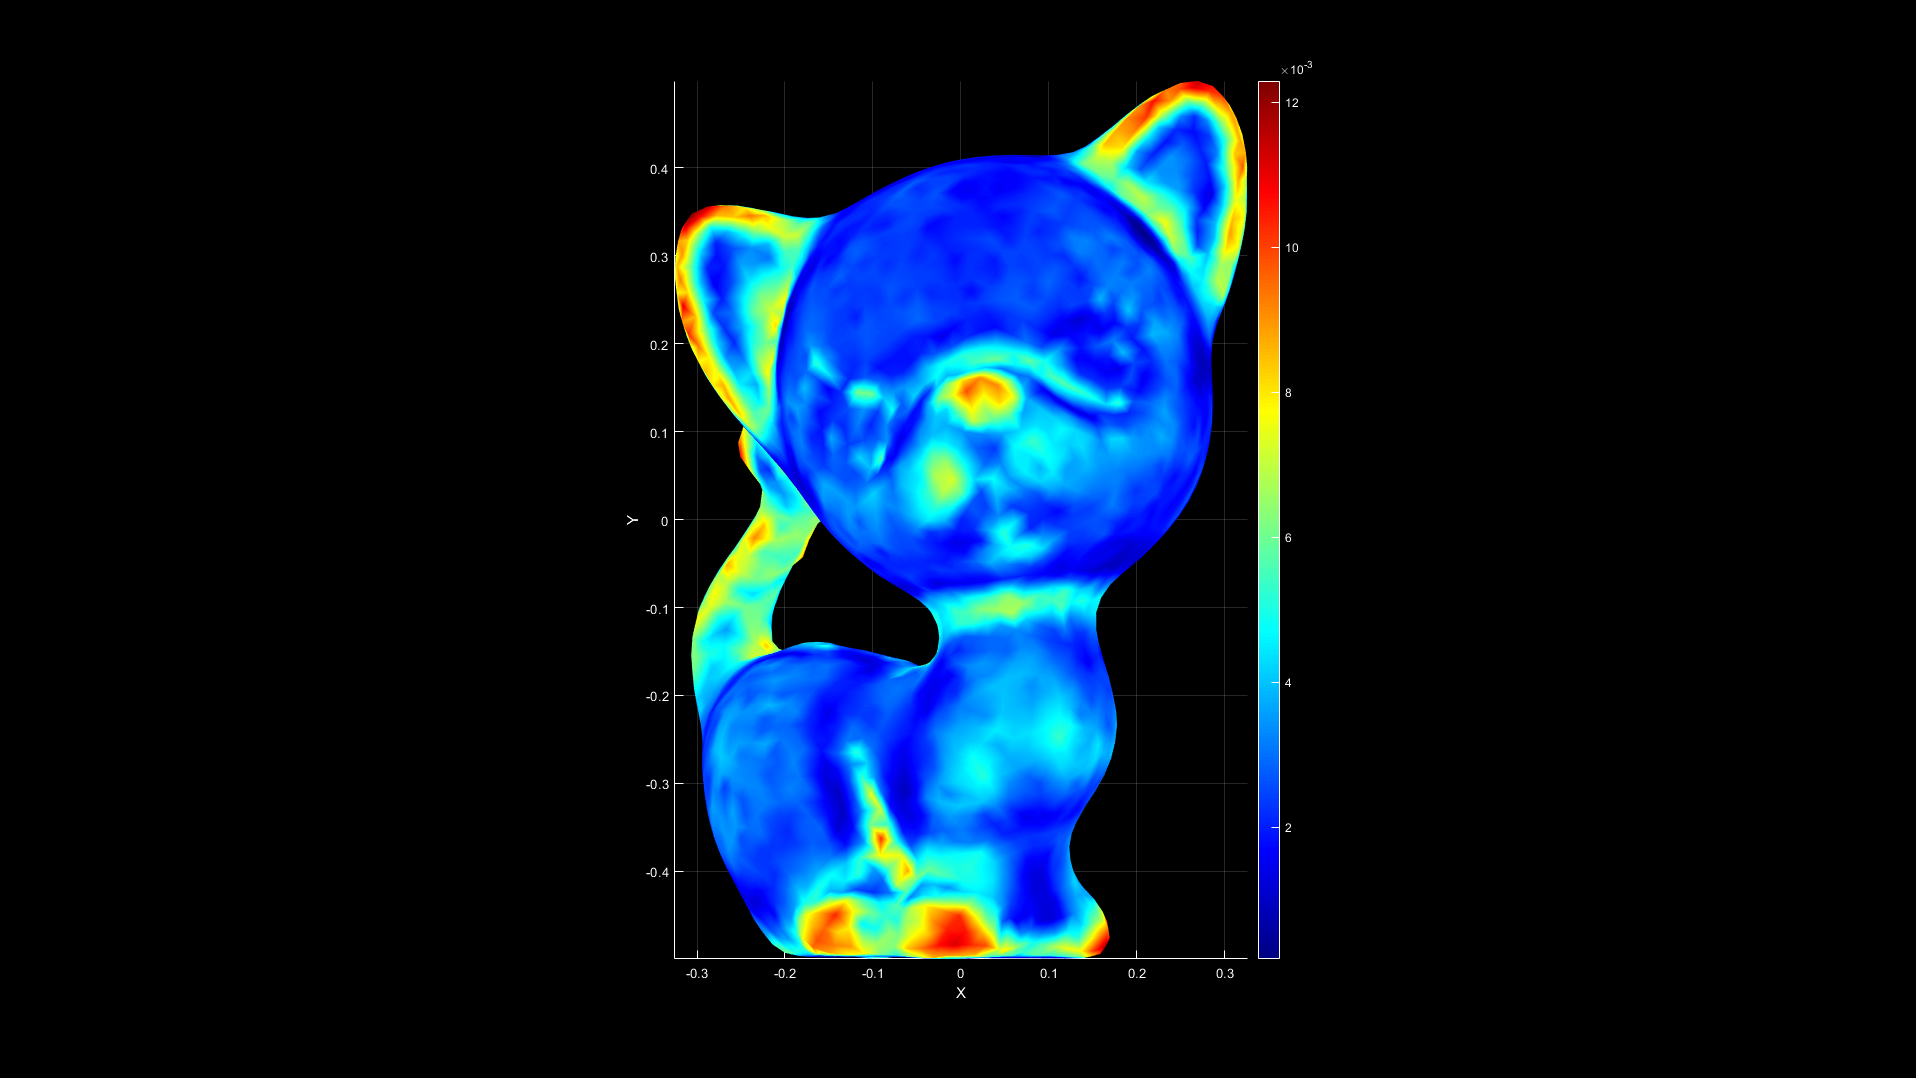

show_mesh_curvature(V,T,curvature);
view(0,90);

### Example #7 : subselection

load('Gargoyle_3k.mat');
plot_mesh(V,T);

Mesh with 1429 vertices and 2836 triangles displayed in 6.974180e-02 seconds.


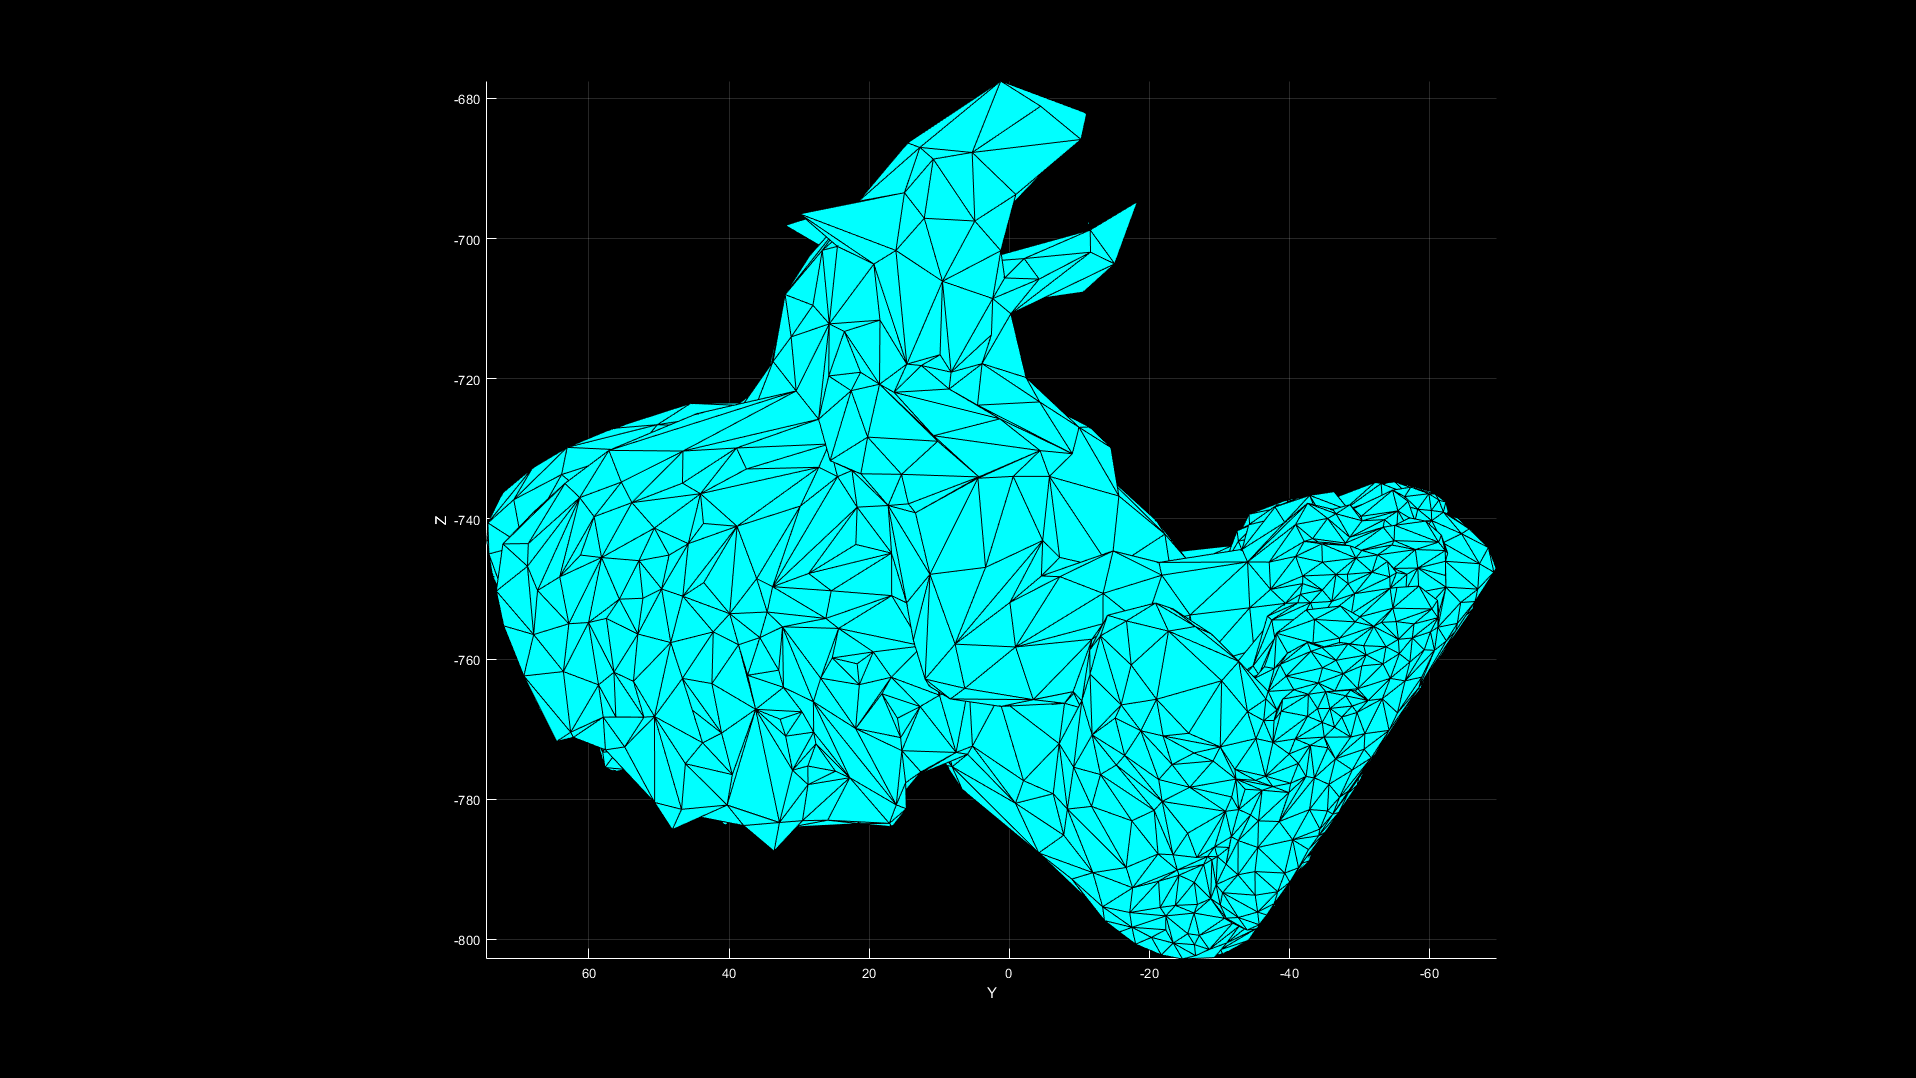

view(-90,0);


n = [0 1 0];
I = [0 -25 800];
[V_out,T_out] = submesh_selection(V,T,n,I); % Gargoyle top part 

submesh with 729 vertices and 4221 triangles selected in 2.052950e-02 seconds.



plot_mesh(V_out,T_out);

Mesh with 726 vertices and 4221 triangles displayed in 6.563190e-02 seconds.


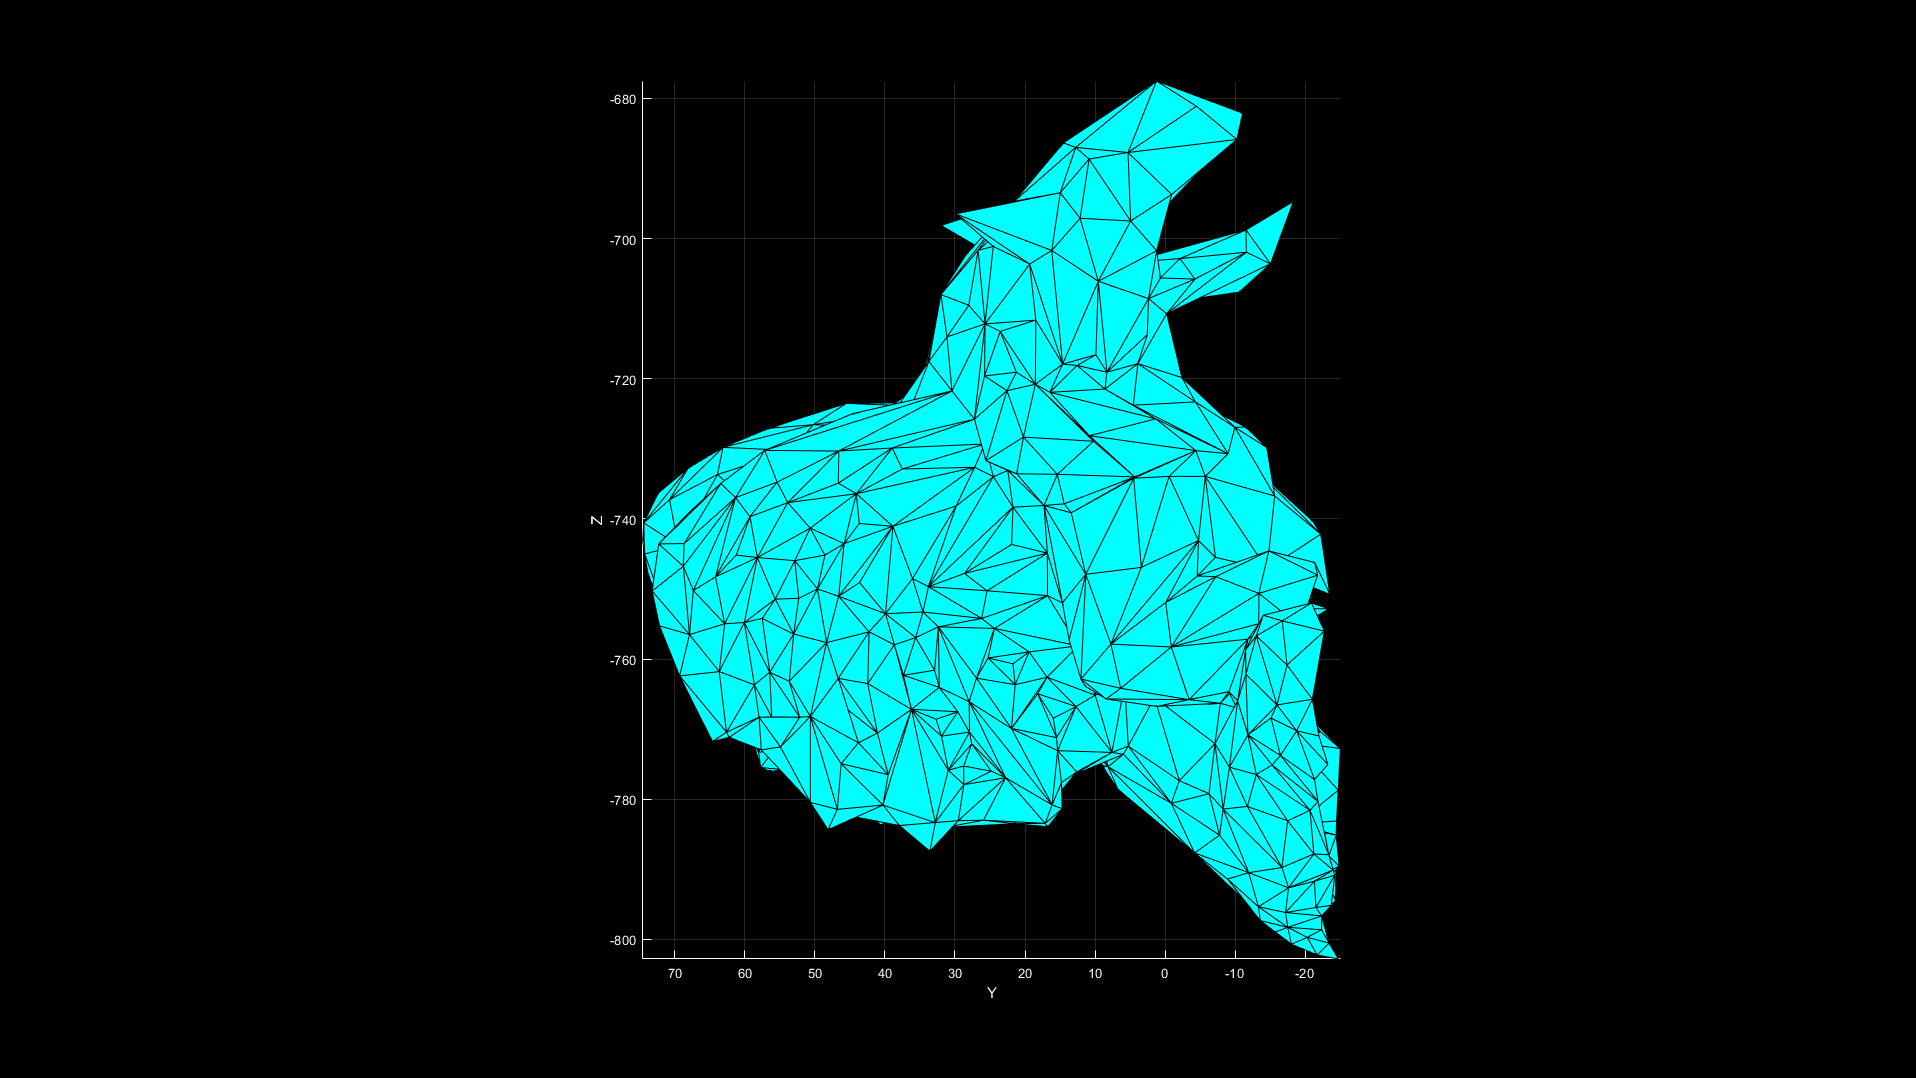

view(-90,0);

### Example #8 : smoothing

plot_mesh(V,T), shading interp, camlight right;

Mesh with 1429 vertices and 2836 triangles displayed in 6.900820e-02 seconds.


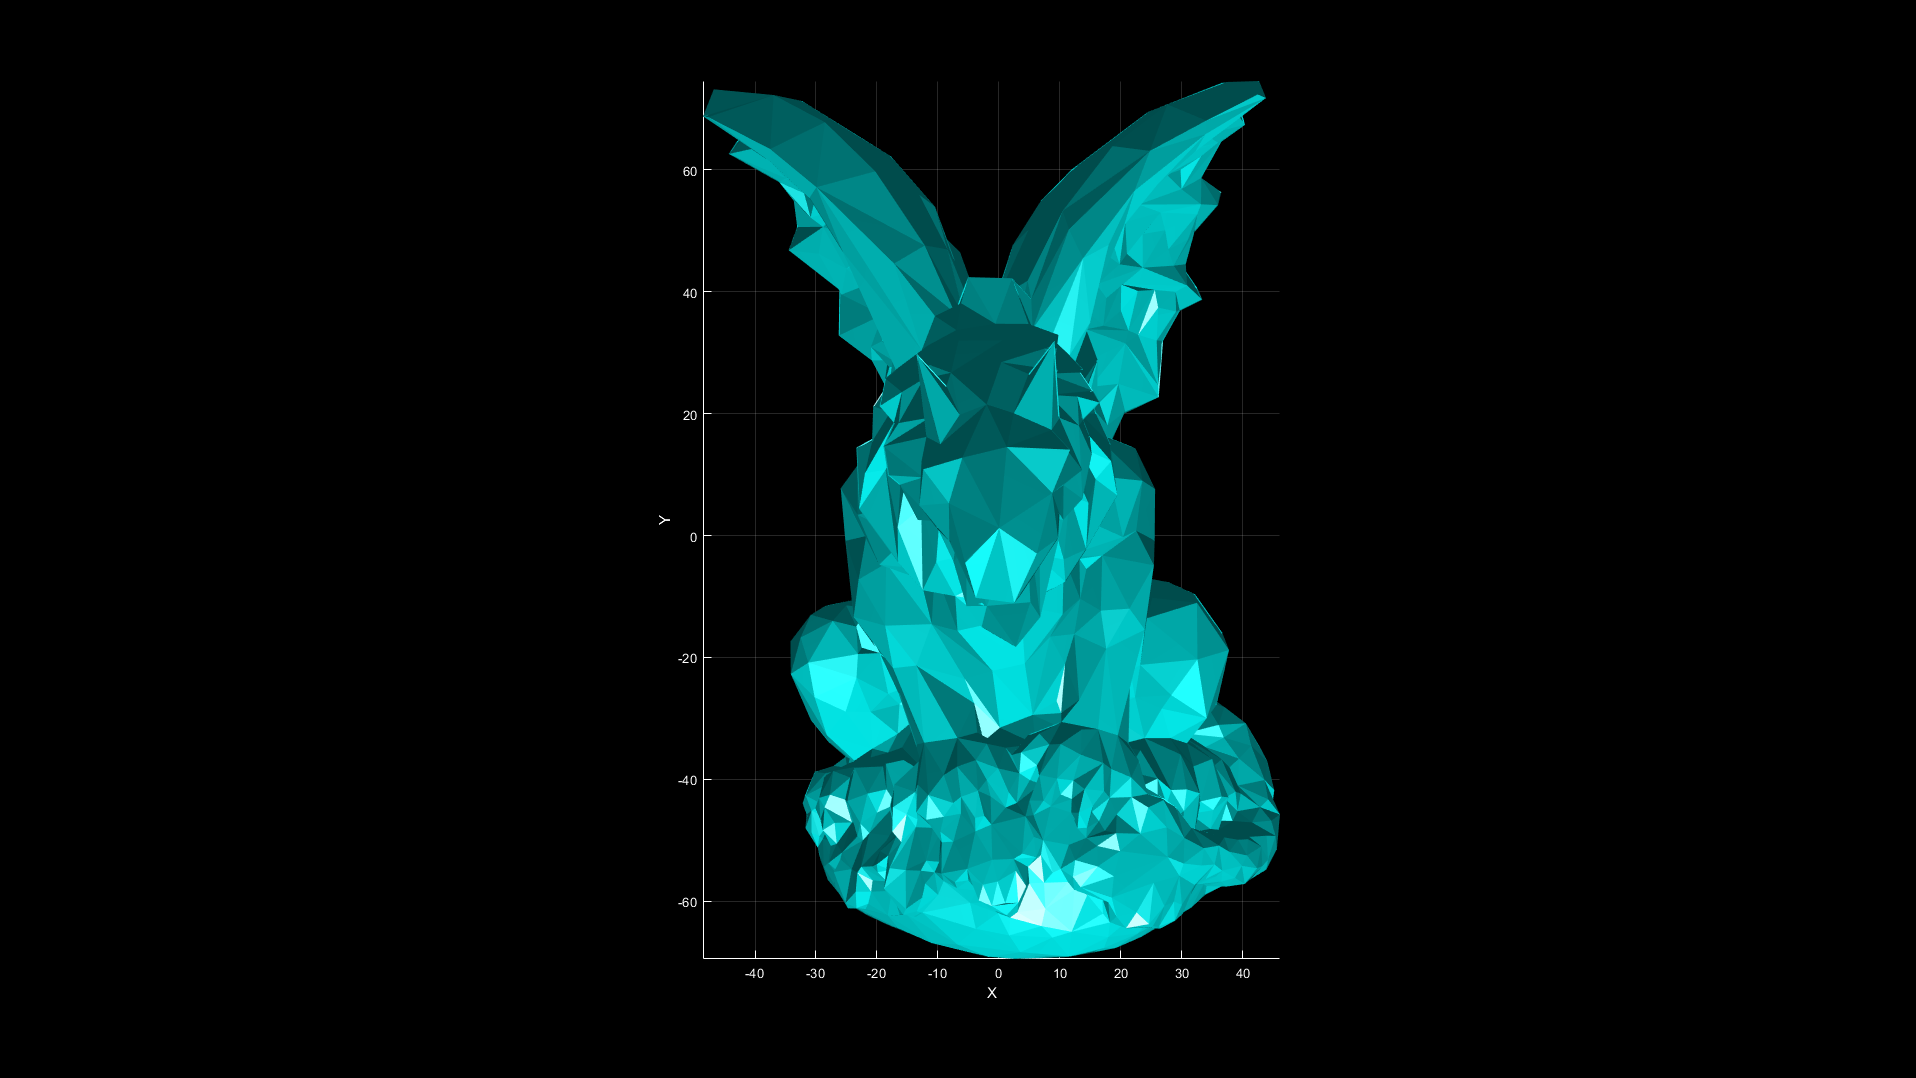

view(0,90);


N = compute_vertex_normals(V,T,2);
nb_iterations = 1;
ngb_degre = 1;
V = mesh_smooth(V,T,nb_iterations,ngb_degre);

Laplacian mesh smoothed in 5.189880e-02 seconds.



plot_mesh(V,T), shading interp, camlight right;

Mesh with 1429 vertices and 2836 triangles displayed in 7.519070e-02 seconds.


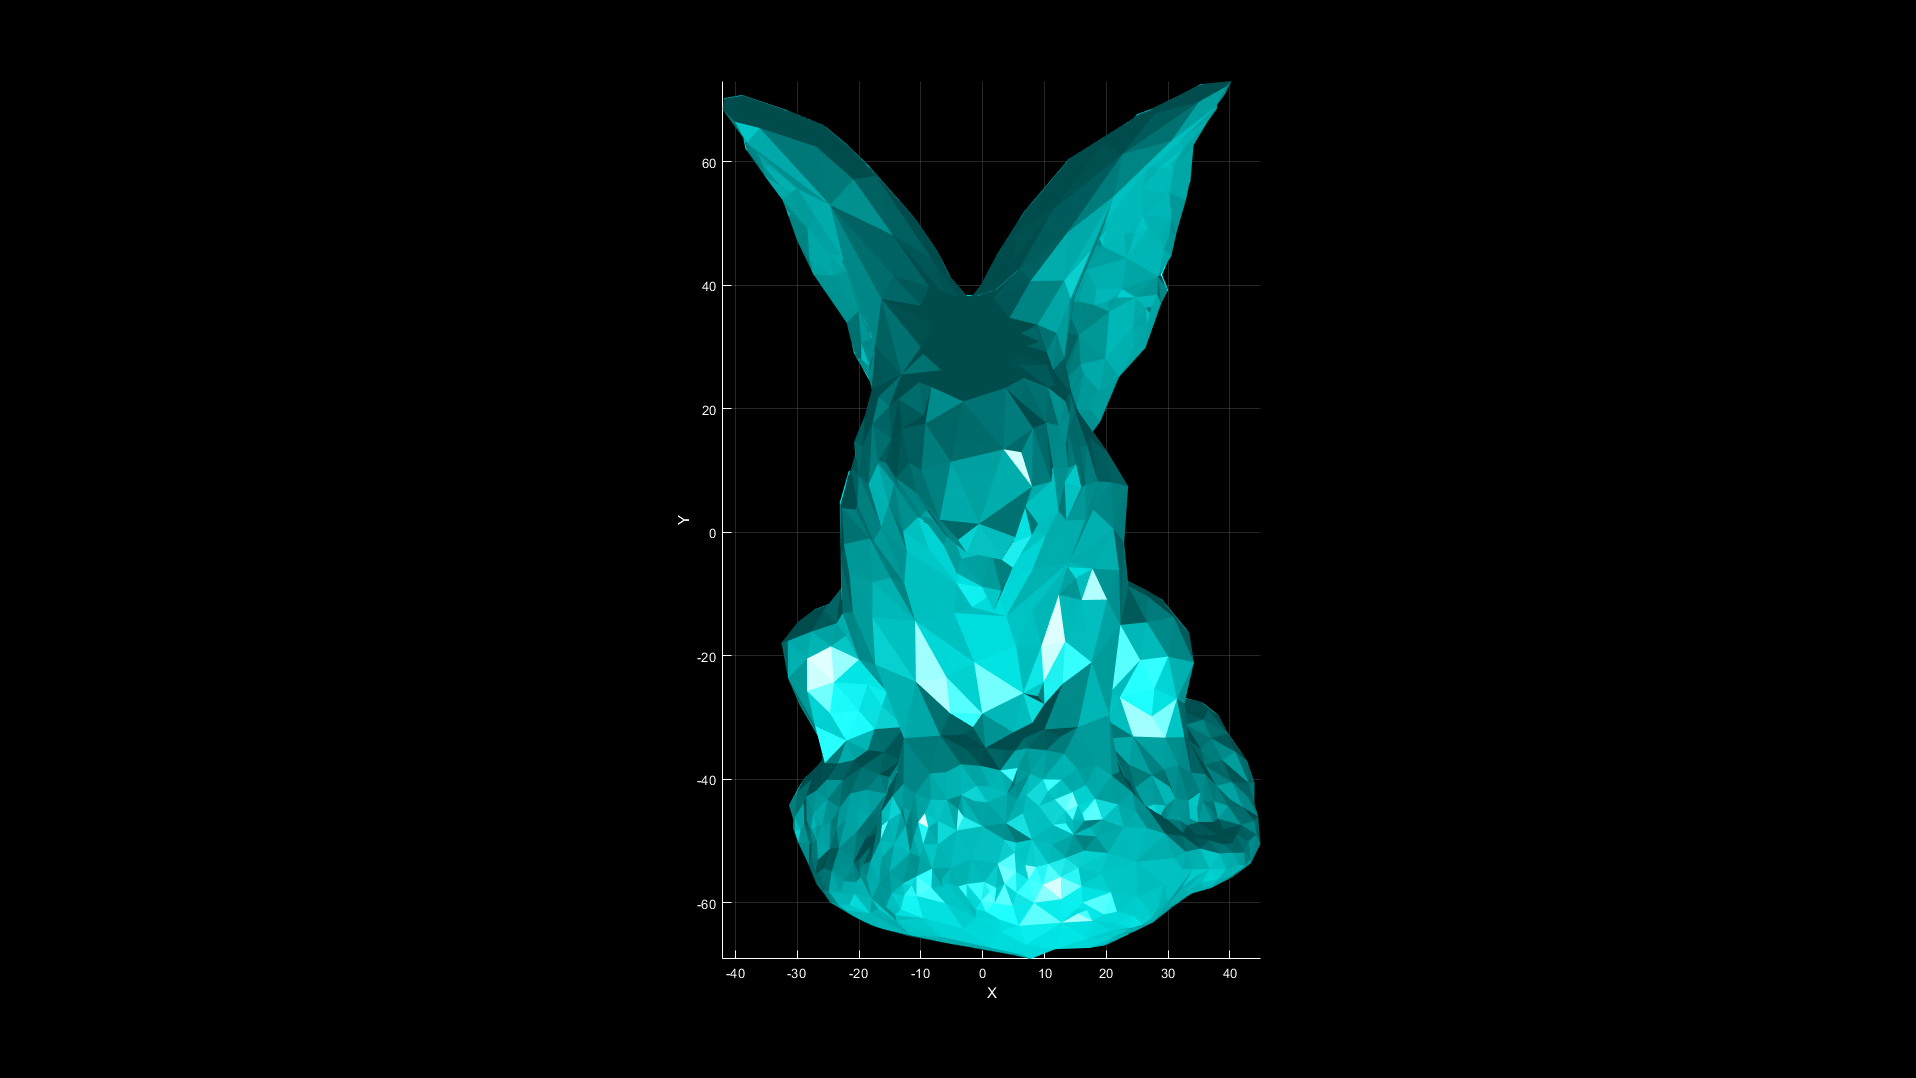

view(0,90);